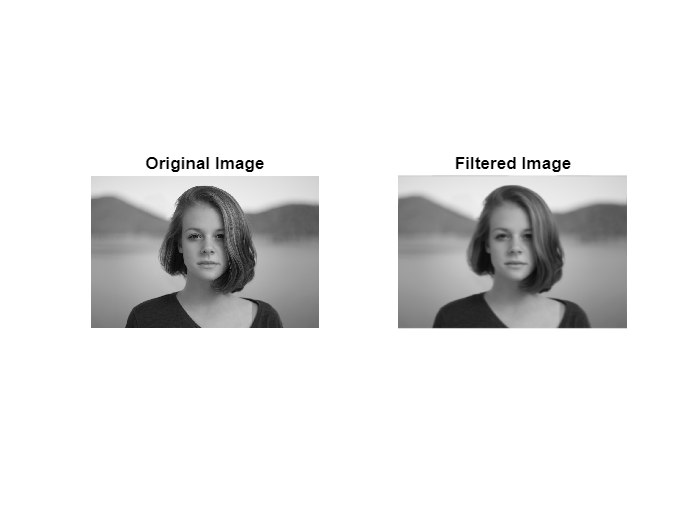

% Load image
img = imread('person.jpeg');

% Convert image to grayscale
gray_img = rgb2gray(img);

% Compute the Fourier transform of the image
fft_img = fft2(double(gray_img));

% Shift the zero-frequency component to the center of the spectrum
fft_img = fftshift(fft_img);

% Define the filter
filter_type = 'gaussian';
D0 = 50;
H = size(gray_img, 1);
W = size(gray_img, 2);
[X, Y] = meshgrid(-(W/2):(W/2-1), -(H/2):(H/2-1));
switch filter_type
    case 'ideal'
        D = sqrt(X.^2 + Y.^2);
        H = double(D <= D0);
    case 'butterworth'
        D = sqrt(X.^2 + Y.^2);
        H = 1./(1 + (D./D0).^(2*5));
    case 'gaussian'
        H = exp(-(X.^2 + Y.^2)/(2*D0^2));
end

% Apply the filter to the Fourier transform of the image
filtered_fft_img = H .* fft_img;

% Shift the zero-frequency component back to the top-left corner
filtered_fft_img = ifftshift(filtered_fft_img);

% Compute the inverse Fourier transform of the filtered image
filtered_img = real(ifft2(filtered_fft_img));

% Show original and filtered images side by side
figure;
subplot(1,2,1);
imshow(gray_img);
title('Original Image');
subplot(1,2,2);
imshow(uint8(filtered_img));
title('Filtered Image');